21 de agosto

Métodos de inteligencia artificial

**Algoritmos genéticos**

**Mutación:**

En una mutación simple, solo un gen (bit) se cambia de forma numérica aleatroia. De 0 a 1 o viceversa.

**Reemplazo generacional:**

Cambiamos la selección inicial con los padres más los hijos generados.

La manera más común para saber si está funcionando es el promedio de desempeño.

clear all; % borrar todas las variables del espacio de trabajo
close all; % cerrar todas las ventanas emergentes
clc; % limpiar la ventana de comandos

Los parámetros iniciales son:

- Población inicial

- Función de ajuste o fitness

- Rango o intervalo

- Cantidad de bits (nbits = 8)

- Cantidad de pobladores (np = 8)


$$y=x^2
$$



$$\left\lbrack 0,255\right\rbrack$$



$$2^8 =256$$


nbits = 8

nbits = 8

np = 8 

np = 8

pobin = randi([0,255],np,1)

pobin =    208
   231
    32
   233
   161
    24
    71
   140


x = pobin;

Proceso en ciclo

for n = 1:100
    y = x.^2 % función de ajuste o fitness o función objetivo
    
    promy(n,1) = mean(y) % ajuste promedio

    cromosoma = [y x]
    
    % selección por ranking (ordenamiento)
    cromosoma = sortrows(cromosoma,1,'descend'); % ordenamiento descendiente
    padredec = cromosoma(1:np/2,2); % padres en decimal
    
    padrebin = de2bi(padredec, nbits); % conversión de decimal a binario
    
    for k=1:np/4
        p = randi([2, nbits - 1]);
        hijobin(2 * k - 1, :) = [padrebin(2 * k - 1, 1:p), padrebin(2 * k, p + 1:nbits)];
        hijobin(2 * k, :) = [padrebin(2 * k, 1:p), padrebin(2 * k - 1, p + 1:nbits)];
    end
    
    % mutación

    p = rand(); % número aleatorio para decidir si muta

    if p >= 0.85 % probabilidad de 15%
        hijo = randi(np/2); % hijo aleatorio
        bit = randi(nbits); % bit aleatorio

        if hijobin(hijo,bit) == 1
            hijobin(hijo, bit) = 0; 
        else
            hijobin(hijo, bit) = 1; 
        end
    end

    hijodec = bi2de(hijobin); % convierte de binario a decimal
    x = [padredec ; hijodec]

end

y =        43264
       53361
        1024
       54289
       25921
         576
        5041
       19600


promy = 2.5384e+04

cromosoma =        43264         208
       53361         231
        1024          32
       54289         233
       25921         161
         576          24
        5041          71
       19600         140


cromosoma =        54289         233
       53361         231
       43264         208
       25921         161
       19600         140
        5041          71
        1024          32
         576          24


padredec =    233
   231
   208
   161


padrebin =      1     0     0     1     0     1     1     1
     1     1     1     0     0     1     1     1
     0     0     0     0     1     0     1     1
     1     0     0     0     0     1     0     1


x =    233
   231
   208
   161
   233
   231
   208
   161


y =        54289
       53361
       43264
       25921
       54289
       53361
       43264
       25921


promy = 1.0e+04 *

    2.5385
    4.4209


cromosoma =        54289         233
       53361         231
       43264         208
       25921         161
       54289         233
       53361         231
       43264         208
       25921         161


cromosoma =        54289         233
       54289         233
       53361         231
       53361         231
       43264         208
       43264         208
       25921         161
       25921         161


padredec =    233
   233
   231
   231


padrebin =      1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     1     1     0     0     1     1     1
     1     1     1     0     0     1     1     1


x =    233
   233
   231
   231
   233
   233
   231
   231


y =        54289
       54289
       53361
       53361
       54289
       54289
       53361
       53361


promy = 1.0e+04 *

    2.5385
    4.4209
    5.3825


cromosoma =        54289         233
       54289         233
       53361         231
       53361         231
       54289         233
       54289         233
       53361         231
       53361         231


cromosoma =        54289         233
       54289         233
       54289         233
       54289         233
       53361         231
       53361         231
       53361         231
       53361         231


padredec =    233
   233
   233
   233


padrebin =      1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x =    233
   233
   233
   233
   233
   233
   233
   233


y =        54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289


cromosoma =        54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma =        54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec =    233
   233
   233
   233


padrebin =      1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x =    233
   233
   233
   233
   233
   233
   232
   233


y =        54289
       54289
       54289
       54289
       54289
       54289
       53824
       54289


promy = 1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231


cromosoma =        54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       53824         232
       54289         233


cromosoma =        54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       53824         232


padredec =    233
   233
   233
   233


padrebin =      1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x =    233
   233
   233
   233
   233
   233
   233
   233


y =        54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289


cromosoma =        54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma =        54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec =    233
   233
   233
   233


padrebin =      1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x =    233
   233
   233
   233
   233
   233
   233
   233


y =        54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289


cromosoma =        54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma =        54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec =    233
   233
   233
   233


padrebin =      1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x =    233
   233
   233
   233
   233
   233
   233
   233


y =        54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 8×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 9×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 10×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 11×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 12×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 13×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 14×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 15×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 16×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 17×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 18×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 19×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 20×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 21×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 22×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 23×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 24×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 25×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   169
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       28561
       54289
       54289


promy = 26×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       28561         169
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       28561         169


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 27×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 28×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 29×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 30×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 31×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 32×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 33×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 34×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   169
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       28561
       54289
       54289
       54289


promy = 35×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       28561         169
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       28561         169


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 36×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   169
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       28561
       54289
       54289
       54289


promy = 37×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       28561         169
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       28561         169


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 38×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 39×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 40×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 41×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 42×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 43×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 44×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 45×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 46×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   225
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       50625
       54289
       54289


promy = 47×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       50625         225
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       50625         225


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 48×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 49×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 50×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   232
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       53824
       54289


promy = 51×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       53824         232
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       53824         232


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 52×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 53×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 54×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 55×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 56×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 57×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   225


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       50625


promy = 58×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       50625         225


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       50625         225


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 59×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 60×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 61×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 62×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 63×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 64×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 65×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 66×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 67×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 68×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   232
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       53824
       54289
       54289


promy = 69×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       53824         232
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       53824         232


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 70×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 71×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 72×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 73×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 74×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 75×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 76×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 77×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 78×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 79×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 80×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 81×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 82×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 83×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   233


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       54289


promy = 84×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   233
   233
   233
   233


padrebin = 4×8
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   233
   233
   233
   233
   233
   233
   233
   237


y = 8×1
       54289
       54289
       54289
       54289
       54289
       54289
       54289
       56169


promy = 85×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       56169         237


cromosoma = 8×2
       56169         237
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   237
   233
   233
   233


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   237
   233
   233
   233
   237
   233
   233
   233


y = 8×1
       56169
       54289
       54289
       54289
       56169
       54289
       54289
       54289


promy = 86×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       54289         233
       54289         233
       54289         233
       56169         237
       54289         233
       54289         233
       54289         233


cromosoma = 8×2
       56169         237
       56169         237
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   237
   237
   233
   233


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     0     1     0     1     1     1
     1     0     0     1     0     1     1     1


x = 8×1
   237
   237
   233
   233
   237
   237
   233
   233


y = 8×1
       56169
       56169
       54289
       54289
       56169
       56169
       54289
       54289


promy = 87×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       54289         233
       54289         233
       56169         237
       56169         237
       54289         233
       54289         233


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       54289         233
       54289         233
       54289         233
       54289         233


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 88×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 89×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   229
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       52441
       56169
       56169
       56169


promy = 90×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       52441         229
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       52441         229


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 91×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 92×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 93×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 94×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 95×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   173
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       29929
       56169


promy = 96×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       29929         173
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       29929         173


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 97×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 98×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 99×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


y = 8×1
       56169
       56169
       56169
       56169
       56169
       56169
       56169
       56169


promy = 100×1
1.0e+04 *

    2.5385
    4.4209
    5.3825
    5.4289
    5.4231
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289
    5.4289


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


cromosoma = 8×2
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237
       56169         237


padredec = 4×1
   237
   237
   237
   237


padrebin = 4×8
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1
     1     0     1     1     0     1     1     1


x = 8×1
   237
   237
   237
   237
   237
   237
   237
   237


Gráfica

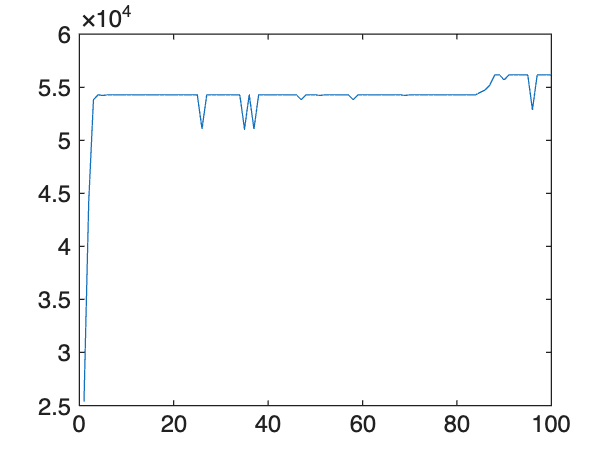

plot(promy)

max(y)

ans = 56169

max(x)

ans = 237